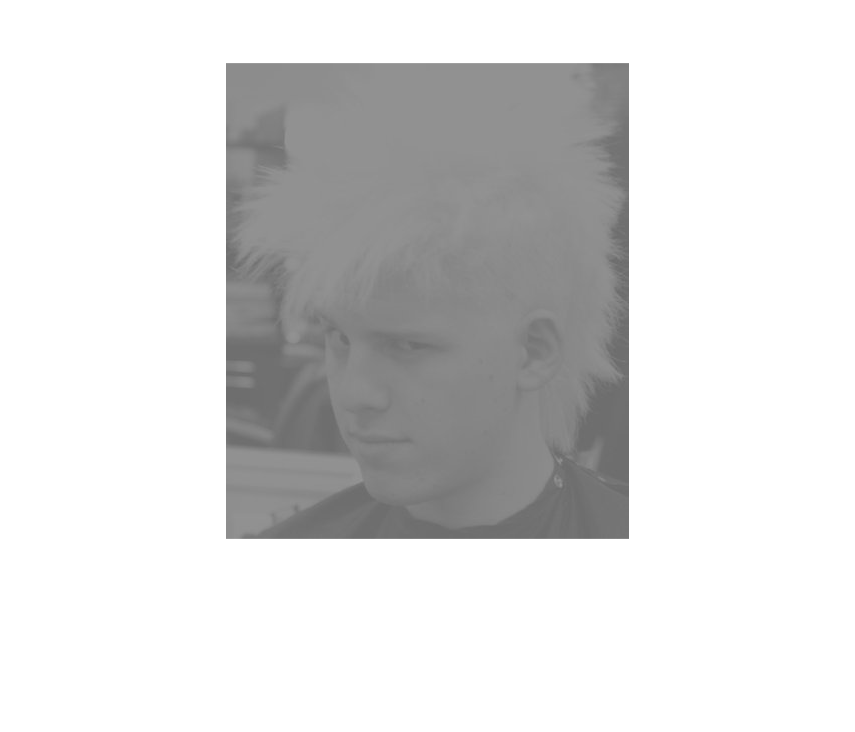

%EXERCICI 1

img = im2double(imread("gabe_low_contrast.jpg"));
figure; imshow(img);

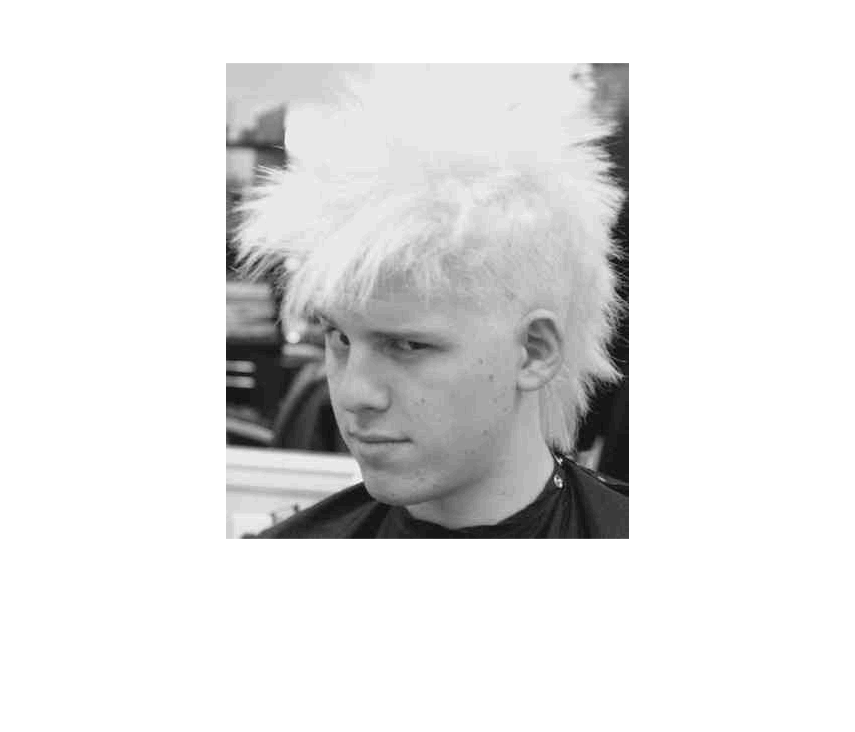


%Augmentem el contrast

minim = min(img,[],'all');
maxim = max(img,[],'all');

img_contrast = imadjust(img,[minim,maxim],[0;1]);
figure; imshow(img_contrast);

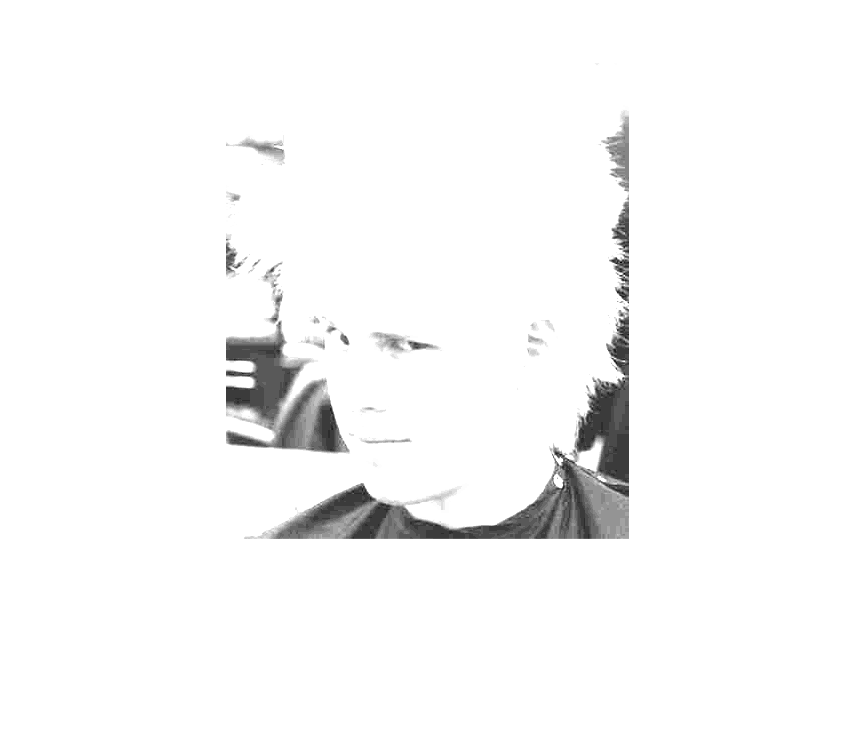


%Expand the dark tones 

img_darker = imadjust(img_contrast,[0;0.4],[0;1]);
figure; imshow(img_darker);

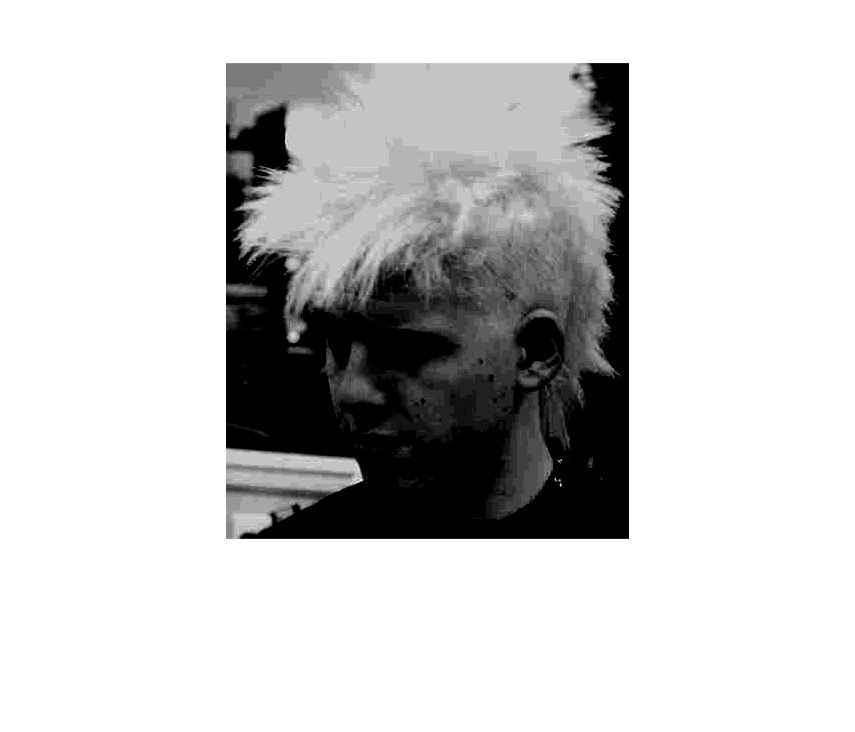


%Expand the light tones

img_lighter = imadjust(img_contrast,[0.6;1],[0;1]);
figure; imshow(img_lighter);

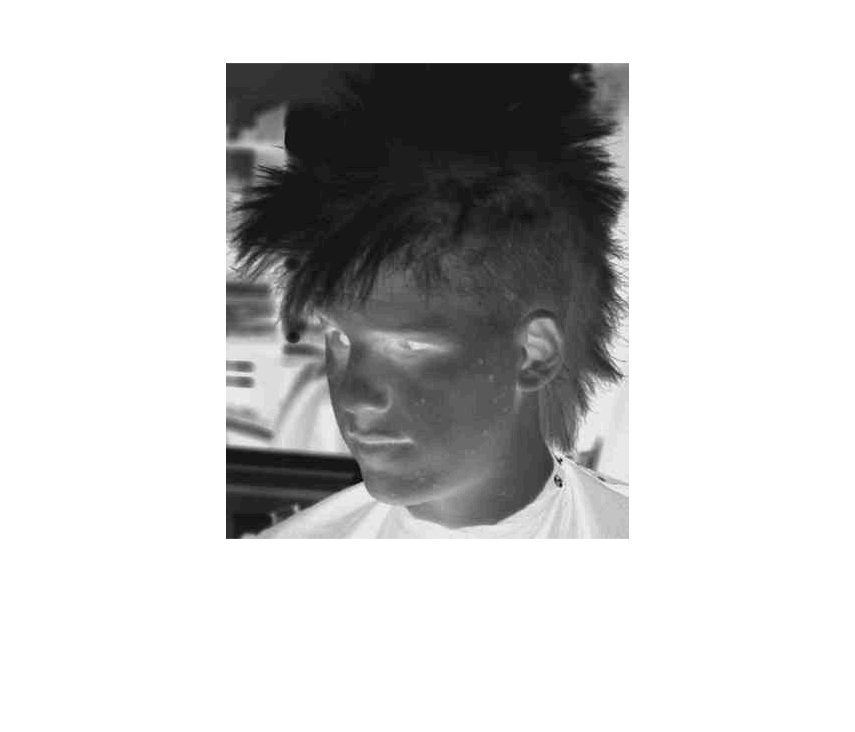


% Invert contrast (negative).

img_inverse = imadjust(img_contrast,[0;1],[1;0]);
figure; imshow(img_inverse);

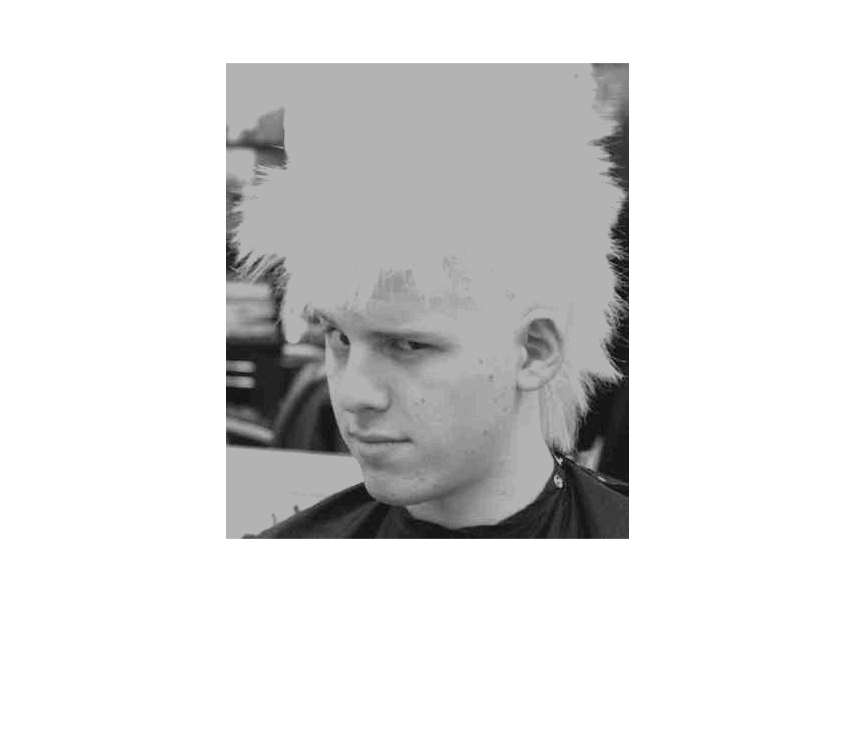


% Crop the levels higher then 0.7

img_crop = imadjust(img_contrast,[0;0.7],[0;0.7]);
figure; imshow(img_crop);

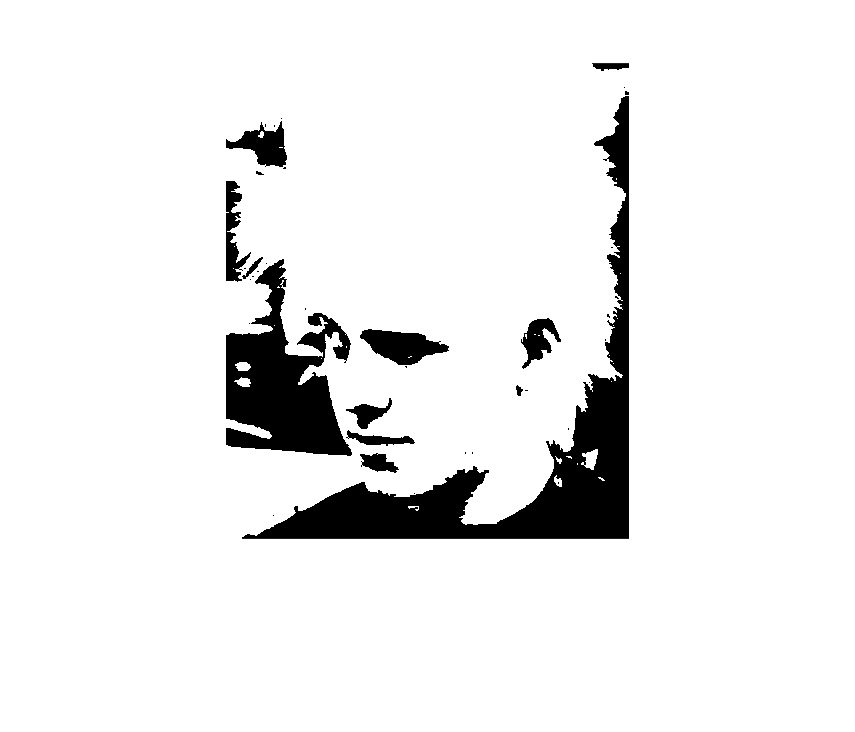


% Binarize at the level 0.5

img_binary = imadjust(img_contrast,[0.499;0.501],[0;1]);
figure; imshow(img_binary);